
temp.curr_timesteps_array = across_experiment_results{1, 1}.timesteps_array;  
temp.curr_active_processing = across_experiment_results{1, 1}.active_processing;

% temp.currData = temp.curr_active_processing.spikes.time(plot_outputs.filter_active_units);
temp.currData = temp.curr_active_processing.spikes.ISIs(plot_outputs.filter_active_units);

temp.currDataFFT = cellfun(@fft, temp.currData, 'UniformOutput', false);

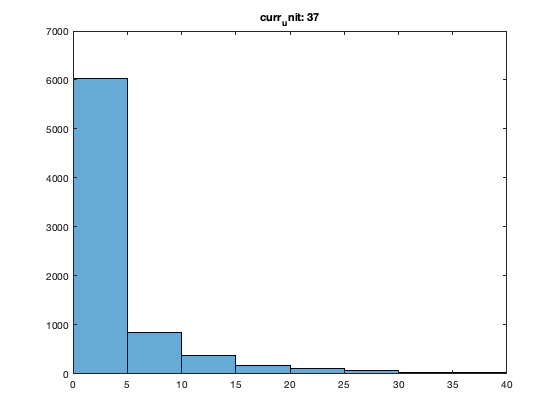

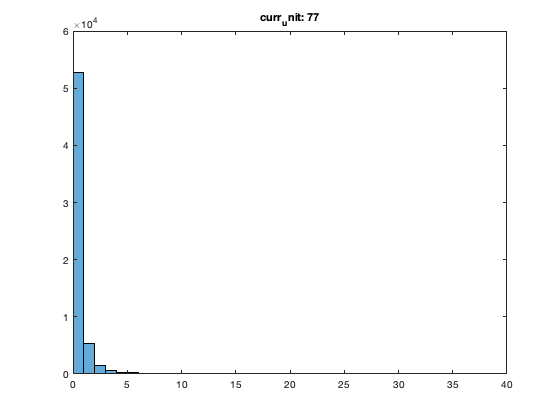

% temp.units_of_interest = [51, 108];
temp.units_of_interest = [37, 77];

for i = 1:length(temp.units_of_interest)
    figure;
    temp.curr_unit_of_interest = temp.units_of_interest(i);
%     plot(abs(temp.currDataFFT{temp.curr_unit_of_interest}));
    [counts, edges] = histcounts(temp.currData{temp.curr_unit_of_interest});
    histogram('BinEdges',edges,'BinCounts',counts)
    title(sprintf('curr_unit: %d', temp.curr_unit_of_interest));
    xlim([0 40]);
end